# Metodi iterativi per la risoluzione di sistemi lineari

Vogliamo risolvere un sistema lineare del tipo $Ax=b$ mediante il metodo di Jacobi.

## Introduzione

Scegliamo come matrice dei coefficienti$A = (a_{ij})\in\mathbb{R}^{N\times N}$ la matrice tridiagonale ottenuta dalla discretizzazione mediante il metodo delle differenze finite del problema di Poisson. L'ordine $N$ di tale matrice quadrata, dipendente dal parametro $n \geq1$, risulta essere $N=n^2$. Inoltre, si tratta di una matrice a dominanza diagonale stretta per righe, ovvero


$$$$\forall\ 1 \leq k \leq N, |a_{kk}| \gt \sum_{j = 1, j \neq k}^{n} |a_{kj}|$$$$


che è una condizione sufficiente per la convergenza del metodo di Jacobi.

clear
n = 250;
N = n^2;
A = distributed(double(gallery('poisson', n)));

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.


fprintf("Size of coefficient matrix A: %u", N);

Size of coefficient matrix A: 62500

Scegliamo come vettore-colonna dei termini noti $b \in \mathbb{R}^N$


$$b = \sum_ {A_{i} \in J} A_{i}$$


dove $J = \{A_{1}, A_{2}, ..., A_{N}\}$denota l'insieme delle colonne della matrice $A$.

b = sum(A,2);

È possibile dimostrare che la soluzione del sistema $x_\text{exact} \in \mathbb{R}^N$ sia pari a


$$x_\text{exact} = [1, 1, ...,1]^T$$


xExact = ones(N,1,'distributed');

## Metodo di Jacobi parallelo con parametri di default

Come primo tentativo, risolviamo il sistema con il metodo di Jacobi, un metodo per la risoluzione di sistemi lineari che ad ogni passo genera una serie di soluzioni approssimate per $x_\text{exact}$.

La funzione `pjm` appartenente al Parallel Jacobi Method Toolbox fornisce un'implementazione parallela del metodo di Jacobi, che restituisce in output una lista di parametri tra cui figurano

- `xJM:` la soluzione approssimata per il sistema $Ax=b$;

- `flagJM`: un flag indicante lo stato di uscita dall'esecuzione del metodo di Jacobi;

- `resvecJM`: un vettore in cui ciascun elemento corrisponde al residuo normalizzato al termine di ogni iterazione, calcolato come  $$ \frac{|| b-Ax ||}{ || b ||}$$.  Si tratta di una metrica indicante l'accuratezza della soluzione calcolata tra un'iterazione e la successiva.

Inoltre, il criterio di arresto del metodo dipende da due parametri in input: `maxit`, il numero massimo di iterazioni, e `tol` rappresentante l'accuratezza della soluzione trovata al termine dell'algoritmo. Nel caso in esame, usiamo la configurazione di default con

`tol` $=10^{-6}$

`maxit` $=100$

tJM_1 = tic;
[xJM_1,flagJM_1,relresJM_1,iterJM_1,resvecJM_1] = jacobi(A,b,[],10000);
tJM_1 = toc(tJM_1);

Procediamo con il calcolo dell'errore assoluto `errJM_1` tra le componenti corrispondenti di $x_\text{exact}$ ed `xJM_1.`

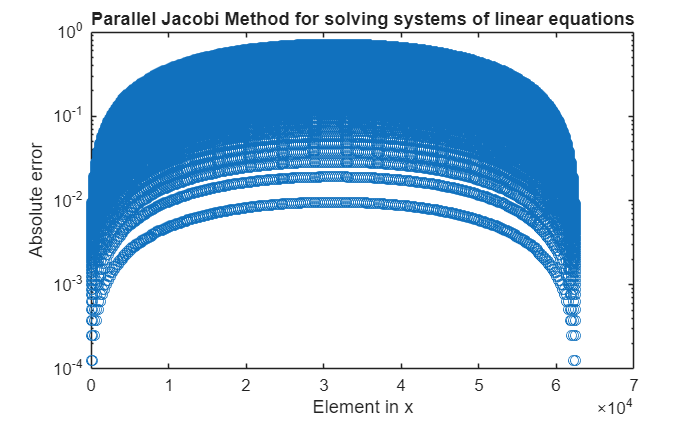

errJM_1 = abs(xExact - xJM_1);

figure(1)
semilogy(errJM_1,'o');
title('Parallel Jacobi Method for solving systems of linear equations');
ylabel('Absolute error');
xlabel('Element in x');

## Metodo di Jacobi classico

Ora risolviamo il sistema $Ax=b$ considerato in precedenza attraverso un'implementazione classica del metodo di Jacobi, in modo da valutare l'effetto sulle prestazioni dovuto alla parallelizzazione dell'algoritmo. 

Ovviamente tutti gli argomenti in input non devono essere più distribuiti sui diversi *worker, *non trattandosi di un problema di calcolo parallelo.

A = gallery('poisson', n);
b = sum(A,2);

Nel caso in esame,

`tol` $=10^{-14}$

`maxit` $=10000$

La funzione s`jm` fornisce un'implementazione classica del metodo di Jacobi, restituendo in output una lista di parametri tra cui figurano `xJM,` `flagJM` e `resvecJM`, con un analogo significato rispetto a quanto descritto per `pjm.`

tJM_2 = tic;
[xJM_2,flagJM_2,relresJM_2,iterJM_2,resvecJM_2] = jacobi(A,b, [], 10000);
tJM_2 = toc(tJM_2);
fprintf("Elapsed time for jacobi with distributed arrays: %f sec.", tJM_1);

Elapsed time for jacobi with distributed arrays: 254.147906 sec.

fprintf("Elapsed time for jacobi: %f sec.", tJM_2);

Elapsed time for jacobi: 8.058463 sec.

Notiamo come il tempo di esecuzione di `pjm` è molto elevato rispetto alla sua controparte seriale, malgrado abbiamo aumentato il numero massimo di iterazioni e abbiamo portato la tolleranza del metodo fino a $10^{-14}$ nel secondo caso. Infatti, il metodo di Jacobi è un algoritmo a bassa intensità computazionale, ovvero esegue un numero relativamente basso di operazioni aritmetiche per ogni byte di dati trasferiti tra i worker. 

Procediamo con il calcolo dell'errore assoluto `errJM_2` tra le componenti corrispondenti di $x_\text{exact}$ e `xJM_2.`

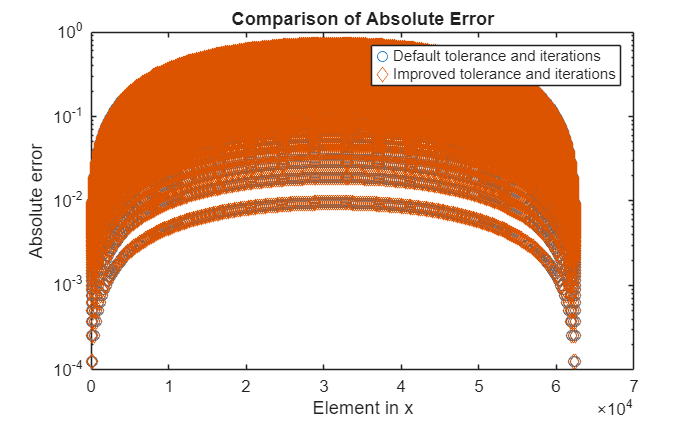

errJM_2 = abs(xExact - xJM_2);

figure(2)
hold off
semilogy(errJM_1,'o');
hold on
semilogy(errJM_2,'d');
title('Comparison of Absolute Error');
ylabel('Absolute error');
legend('Default tolerance and iterations','Improved tolerance and iterations');
hold off
xlabel('Element in x');

Procediamo con il calcolo dei residui relativi al secondo tentativo per individuare il motivo per cui il metodo di Jacobi è risultato non convergente nel primo caso.

relresvecJM = resvecJM_2./resvecJM_2(1);

Dal grafico in figura, notiamo come sia impossibile raggiungere una soluzione sufficientemente approssimata per il sistema in questione con il numero di iterazioni di default.

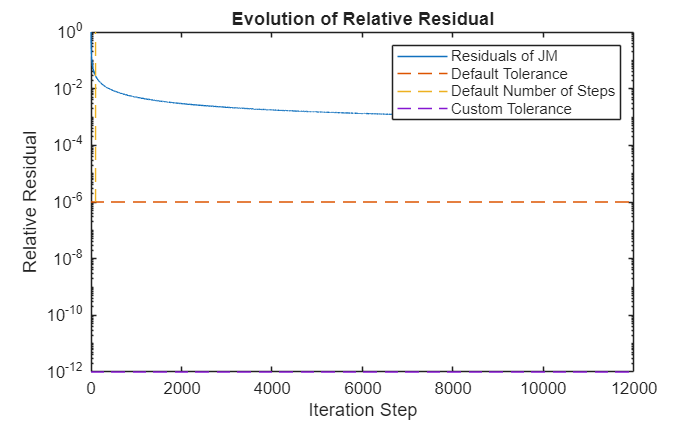

figure(3)
f=semilogy(relresvecJM);
hold on
semilogy(f.Parent.XLim,[1e-6 1e-6],'--')
semilogy([100 100], f.Parent.YLim,'--')
semilogy(f.Parent.XLim,[1e-12 1e-12],'--')
title('Evolution of Relative Residual');
ylabel('Relative Residual');
xlabel('Iteration Step');
legend('Residuals of JM','Default Tolerance','Default Number of Steps','Custom Tolerance')
hold off

Al termine delle elaborazioni, possiamo spegnere il *parallel pool *di *worker *attualmente attivo.

%delete(gcp('nocreate'))

Inoltre, la velocità di convergenza del metodo è bassa rispetto ad altri metodi iterativi, come dimostrato dalla mancata convergenza a causa del numero limitato di iterazioni a disposizione nel primo caso.

fprintf("flagJM_1 = %u e flagJM_2 = %u", flagJM_1, flagJM_2);

flagJM_1 = 1 e flagJM_2 = 1

Per questi motivi, in problemi *computation-intensive *si preferisce utilizzare un solutore con una velocità di convergenza maggiore, come il metodo del gradiente coniugato precondizionato, rilegando l'uso del metodo di Jacobi come precondizionatore al fine di accelerare la convergenza del solutore principale. 